## Biometric Fusion based Identification (PPG, ECG, SQRT)

from BioMetric_ECG_PPG_SQRT_MDPI_V1.csv the fusion colum values or "SQRT" is taken as input.

The 28,000 rows of signal data is broken into many smaller instances based on window size of the signal frequency "minOneBeat". The inputs are taken into non decimal value to calcluate features [ as pentropy feature could not be calculated from decimal values ]

The loop ensures all the user data is taken into the input matrix.

%
clear all;
% # of data amplitude reading to be used as one sample sequence
minOneBeat = 150 * 20;
% fs means here Frequecy of features to be used in training the sequence
fs = 100;
maxEpochs = 100 ;
initialLearnRate = 0.01;
% Batch size depends on total sample sequence
miniBatchSize = 32;
% layer size for the sequence learning
hiddenLayers = 2;
optimizer = 'sgdm';
GradientThreshold = 0.25;
% The user to test with the traning and testing the model
targetUser = 1;
valid_Usr = "Valid-User";
invalid_Usr = "Attacker";
numClasses = 2;
% instfreq and pentropy
numberOfFeatures = 2;
load("Merged_PPG_ECG_SQRT_State1.mat");
input = mergedTable1;


Fathur Rahman

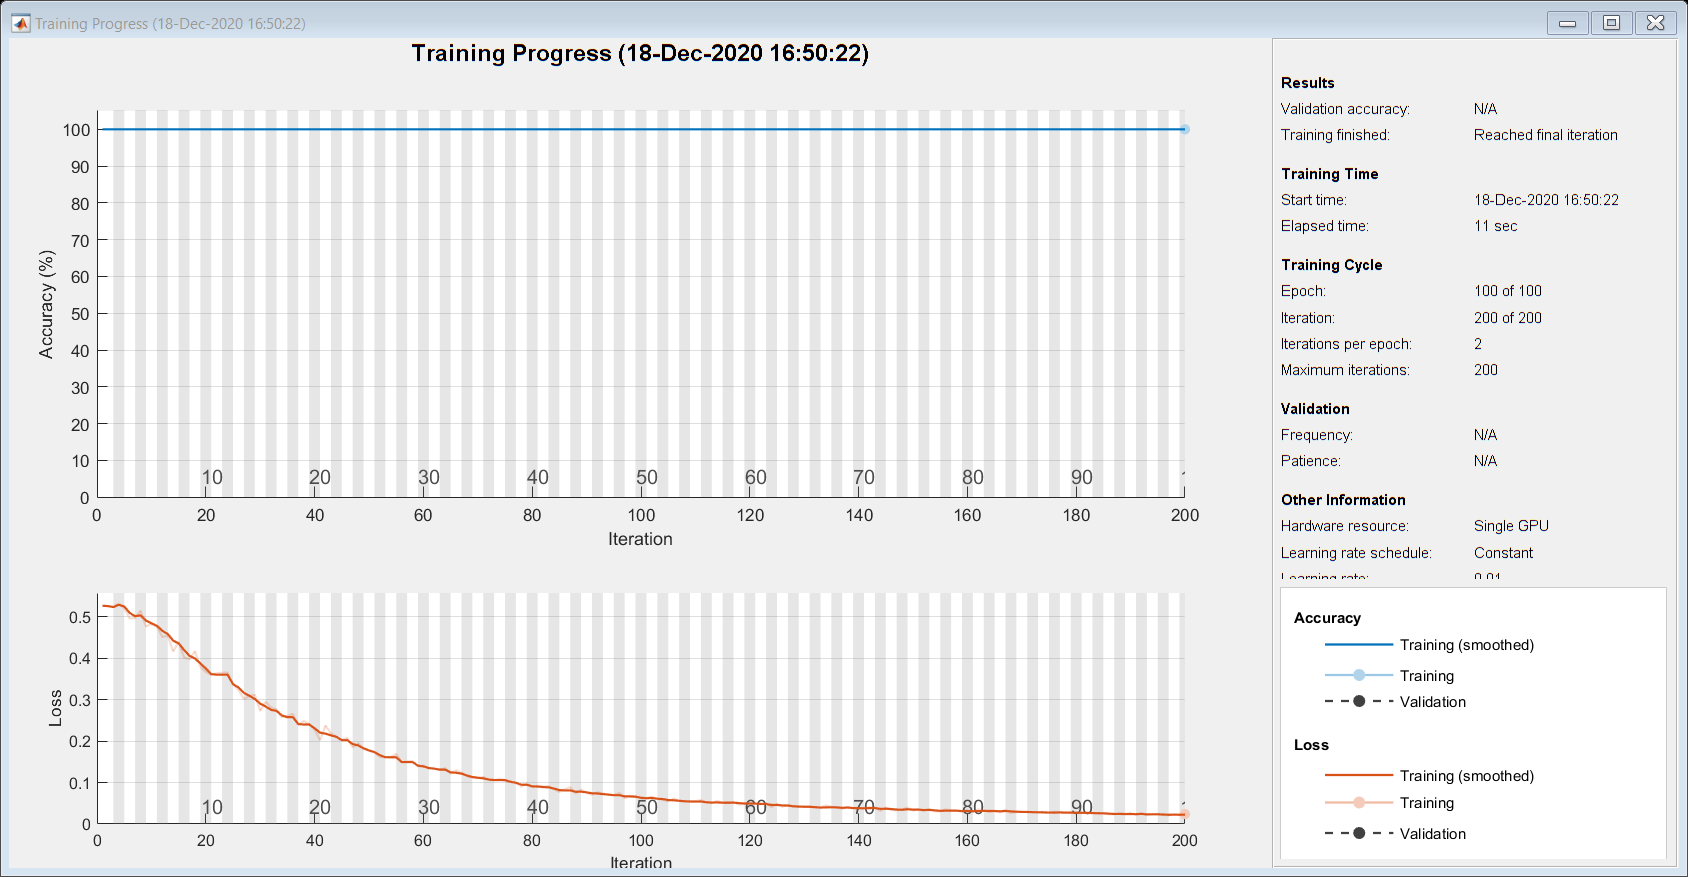

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |      100.00% |       0.5269 |          0.0100 |
|      25 |          50 |       00:00:04 |      100.00% |       0.1775 |          0.0100 |
|      50 |         100 |       00:00:06 |      100.00% |       0.0622 |          0.0100 |
|      75 |         150 |       00:00:09 |      100.00% |       0.0323 |          0.0100 |
|     100 |         200 |       00:00:11 |      100.00% |       0.0239 |          0.0100 |
|========================================================================================|



% Rounding the decimal to integer
input = round(input);
% --------Denoising---------------------
%input = smoothdata(input,'movmean',1)
%
[rows,cols] = size(input);
usr = cols/3;
% Manually setting user #
usr = 10;

i=1;
j=1;
k = 1;
targetUserColNo = 3;
sample = round(rows/minOneBeat)-1;
loop = 1;

% k+2 mean taking SQRT dataset
for m = 1:usr
    for l = 1:sample
        if (rows > j+minOneBeat)
            trainingInput = input(j:j+minOneBeat-1,k+2)';

            if (m == targetUser)
                % Swap the targer User data in front of the Input data
                % Otherwise the model is not trained properly
                if(m == 1)
                    XTrain_cell{loop,1} = trainingInput(1,:);
                    target2{loop,1} = valid_Usr;
                    target3(loop,1) = valid_Usr;
                else    
                    XTrain_cell{loop,1} = XTrain_cell{l,1};
                    XTrain_cell{l,1} = trainingInput(1,:);
                    target2{loop,1} = invalid_Usr;
                    target3(loop,1) = invalid_Usr;
                    target2{l,1} = valid_Usr;
                    target3(l,1) = valid_Usr;
                end
                targetUserColNo = k+2;
            else
                XTrain_cell{loop,1} = trainingInput(1,:);
                target2{loop,1} = invalid_Usr;
                target3(loop,1) = invalid_Usr;
            end
            j = i * minOneBeat + 1 ;
            loop = loop + 1;
        end
    end
    k = i*3+1;
    j = 1;
    i = 1;
end
% loop value to continue to create duplicates of valid user
% Duplicating Valid User record to avoid class imbalance
for m = 1:round(usr/2)
    j = 1;
    i = 1;
    for l = 1:sample
        if (rows > j+minOneBeat)
            trainingInput = input(j:j+minOneBeat-1,targetUserColNo)';
            XTrain_cell{loop,1} = trainingInput(1,:);
            target2{loop,1} = valid_Usr;
            target3(loop,1) = valid_Usr;
            loop = loop + 1;
            j = i * minOneBeat + 1 ;
        end
    end
end

layers = [ ...
    sequenceInputLayer(numberOfFeatures)
    bilstmLayer(hiddenLayers,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
    ];
options = trainingOptions(optimizer, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'InitialLearnRate', initialLearnRate, ...
    "Shuffle","every-epoch",...
    'GradientThreshold', GradientThreshold, ...
    'plots','training-progress', ...
    'Verbose',true);



    data = [XTrain_cell,target2];
    % Data partition (NON RANDOM) (train: 70%, test: 30%)
    
    PD = 0.30 ;  % 30% Test 70% train
    % Let P be your N-by-M input dataset
    % Solution-1 (need Statistics & ML Toolbox)
    %target1 = categorical(target1);
    % target2 and target3 holds same value
    cv = cvpartition(target3,'HoldOut',PD);
    dataTrainCombo = data(cv.training,:);
    dataTestCombo = data(cv.test,:);
    dataTrainTarget = dataTrainCombo(:,2);
    dataTrainTarget = string(dataTrainTarget);
    dataTrain = dataTrainCombo(:,1);
    dataTest = dataTestCombo(:,1);
    dataTestTarget = dataTestCombo(:,2);
    dataTestTarget = string(dataTestTarget);    
    
    dataTrain = cellfun(@(x)normalize(x)',dataTrain,'UniformOutput',false); 
    instfreqTrain1 = cellfun(@(x)instfreq(x,fs)',dataTrain,'UniformOutput',false);
    pentropyTrain1 = cellfun(@(x)pentropy(x,fs)',dataTrain,'UniformOutput',false);
    XTrain1_2 = cellfun(@(x,y)[x;y],instfreqTrain1,pentropyTrain1,'UniformOutput',false);
    
    XV1 = [XTrain1_2{:}];
    mu1 = mean(XV1,2);
    sg1 = std(XV1,[],2);
    XTrainSD = cellfun(@(x)(x-mu1)./sg1,XTrain1_2,'UniformOutput',false);
    net2 = trainNetwork(XTrainSD,categorical(dataTrainTarget),layers,options);   

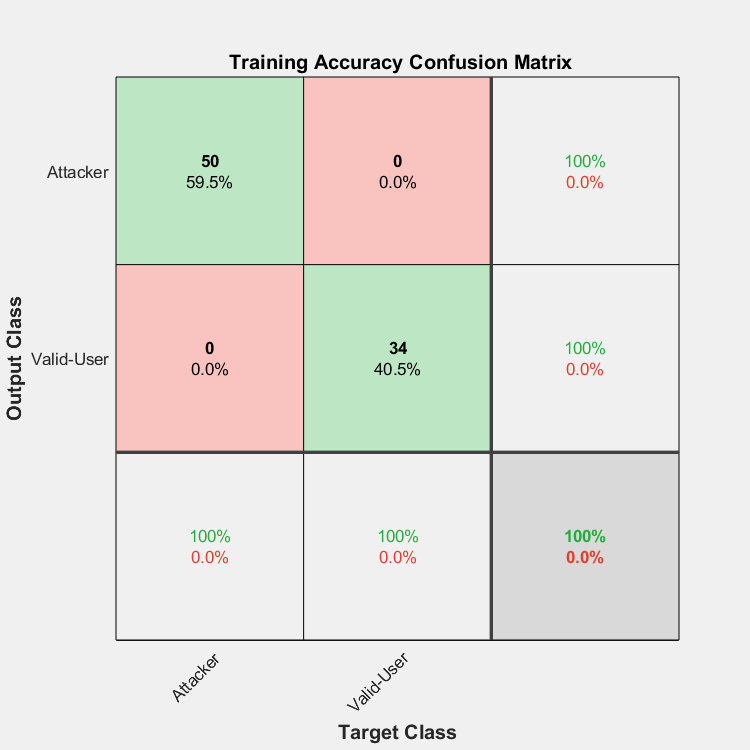

%     net2 = trainNetwork(XTrain1_2,categorical(dataTrainTarget),layers,options);    
    txtTrain = ' Training Accuracy';
    txtTest = ' Testing Accuracy';
    
    trainPred = classify(net2,XTrainSD);
    catTrain = categorical(dataTrainTarget);
    figure;
    plotconfusion(categorical(dataTrainTarget'),trainPred',txtTrain);

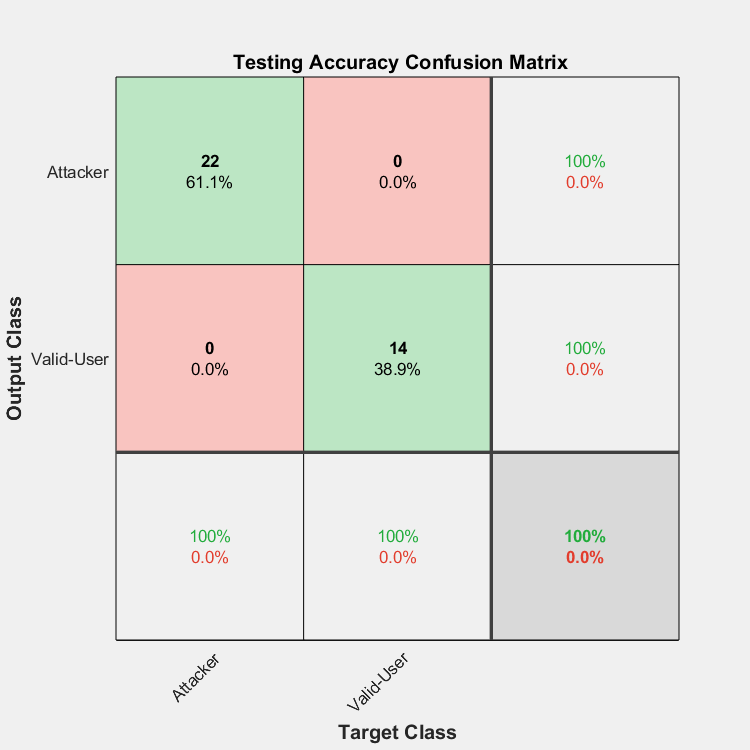

    
    %Normalize the data
    dataTest = cellfun(@(x)normalize(x)',dataTest,'UniformOutput',false);
    instfreqTest1 = cellfun(@(x)instfreq(x,fs)',dataTest,'UniformOutput',false);
    pentropyTest1 = cellfun(@(x)pentropy(x,fs)',dataTest,'UniformOutput',false);
    XTest1_2 = cellfun(@(x,y)[x;y],instfreqTest1,pentropyTest1,'UniformOutput',false);
    
    XV1 = [XTest1_2{:}];
    mu1 = mean(XV1,2);
    sg1 = std(XV1,[],2);
    XTestSD1_2 = cellfun(@(x)(x-mu1)./sg1,XTest1_2,'UniformOutput',false);
        
    testPred1 = classify(net2,XTestSD1_2);
    catTest = categorical(dataTestTarget);
    figure;
    plotconfusion(categorical(dataTestTarget'), testPred1', txtTest );